# ME 4501 Lab 10: Position Control Using Quanser Qube 

# Dr. Ayse Tekes

**Due: A week after the lab. I will be grading your lab report individually in the beginning of the class.**

**Learning Objectives:**

- Control the angular position of servo by designing a PID controller using Quanser Qube

**A. Theory**

Quanser Qube transfer function from input Voltage ($V_m$) to Angular Position ($\theta_m$) is

$G\left(s\right)=\frac{\theta_m \left(s\right)}{V_m \left(s\right)}=\frac{K}{s\left(\tau s+1\right)}$            (1)

where K = 22.4 rad/(Vs) is the model steadystate gain, τ = 0.15 s is the model time constant, and also

## Position Control of Quanser Qube

**Learning Outcomes:**

- Design a PD controller so that the closed loop system have the desired transient response specifications

- Create MATLAB Simulink model to test the controller using real time controller with Quanser Qube

- Measure the corresponding performance specifications

- Determine the effect of proportinal and derivative controller on system performance

**Lab Procedures**

**1.** Find the closed loop system transfer function of the given block diagram

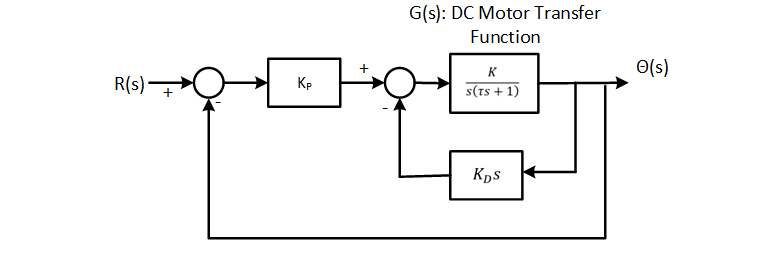

where G(s) is the DC motor transfer function. We found the transfer function in the Step Response Lab as below


$$G\left(s\right)=\frac{K}{s\left(\tau s+1\right)}=\frac{23}{s\left(0\ldotp 166s+1\right)}$$


syms s K tau Kp Kd
G=K/(s*(tau*s+1));
G2=Kd*s;
G3=Kp;
N=G/(1+G*G2)

$$N = \frac{K}{s\,\left(\frac{K\,\mathrm{Kd}}{s\,\tau +1}+1\right)\,\left(s\,\tau +1\right)}$$

T=collect(simplify(N*G3/(1+N*G3)),s)

$$T = \frac{K\,\mathrm{Kp}}{\tau \,s^{2}+\left(K\,\mathrm{Kd}+1\right)\,s+K\,\mathrm{Kp}}$$

**2.** Find the proportional (Kp) and Derivative (Kd) controller constants so that the system transient response will exhibit 10% overshoot and 0.3 sec settling time.

K=23;
tau=0.166;
OS=0.1;
Ts=0.3;
zeta=sqrt((log(OS)/-pi)^2/((log(OS)/-pi)^2+1))

zeta = 0.5912

wn=4/(Ts*zeta)

wn = 22.5547

Kp=wn^2*tau/K

Kp = 3.6716

Kd=(2*zeta*wn*tau-1)/K

Kd = 0.1490

Ki=0

Ki = 0

**3.** Create the Simulink model in MATLAB as shown below and run the simulations for 10 seconds using Quanser Qube. The signal genereator amplitude is 1 V and the frquany is 0.5 Hz. 

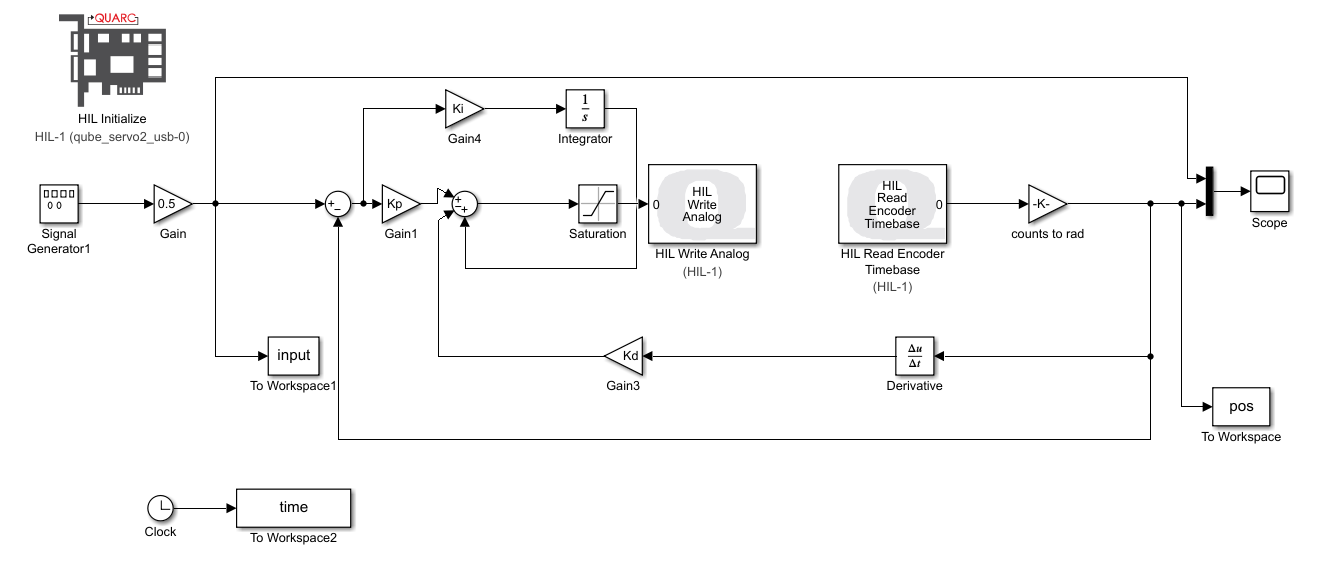

**4.** Plot the response of the system and calculate the maximum overshoot and settling time. 

**5. **Tune the parameters of the controller (Kp and Kd) to see their effects on the system response and create a table below including the Kp values, Overshoot, Settling Time, and steady-state error.

**Discussion**

**1.** What is the effect of propotional gain (Kp) on the servo position?

**2.** What is the effect of derivative controller (Kd) on the servo position?

**3.** Simulate the same system using transfer function and compare the two outputs (simulated angular position and Quanser Qube angular position). 

**4.** Can we meet all the design specifications using only proportional or proportional and derivative controller?